
close all
clear all
colors=npg(10); % Ten basic colors 
tpi = 2*pi;
gamma171 = 7.5e6;   % freq, Hz/T

% near %
maindir='\\Artemis-pc\Data\2026-04-20\Abs-330\';   % 靠近，对比度
load([maindir,'\FitResult.mat']);

a171n = amp2;   % 171 对比度
a171n_sigma = a_sigma2;
T171n = T2;
a173n = amp;   % 173 对比度
a173n_sigma = a_sigma;
T173n = T;

% far %
maindir='\\Artemis-pc\Data\2026-04-20\Abs-330\';   % 远离，对比度
load([maindir,'\FitResult.mat']);

a171f = amp2;   % 171 对比度
a171f_sigma = a_sigma2;
T171f = T2;
a173f = amp;   % 173 对比度
a173f_sigma = a_sigma;
T173f = T;

maindir='\\Artemis-pc\Data\2026-04-20\Abs-437\';   % 相位数据
main_dir_0=maindir;
load([maindir,'\population.mat']);



% ！！注意修改 周期数 和 进动时间 ！！ %

tau_s = 6;   % s，不包含旋转位移台时间
tau_ms = 20;   % ms
coefficient171 = -1;
coefficient173 = -1;

R_list = -[1 -1 -1 1 -1 1 1 -1];   % 旋转序列，靠近(1)，远离(-1)
Rlen = length(R_list);
for k = 1:Rlen
    if R_list(k) == 1
        a171(k) = a171n;
        a171_sigma(k) = a171n_sigma;
        T171(k) = T171n;
        a173(k) = a173n;
        a173_sigma(k) = a173n_sigma;
        T173(k) = T173n;
    elseif R_list(k) == -1
        a171(k) = a171f;
        a171_sigma(k) = a171f_sigma;
        T171(k) = T171f;
        a173(k) = a173f;
        a173_sigma(k) = a173f_sigma;
        T173(k) = T173f;
    end
end

a171 = amp2;   % 171 对比度
a171_sigma = a_sigma2;
T171 = T2;

a173 = amp;   % 173 对比度
a173_sigma = a_sigma;
T173 = T;

% 进动时间，秒数在第一段修改 %
precession = tau_s*1e3 + tau_ms;   % 时序可设置的进动时间
precession_total = (tau_s+2*2)*1e3 + tau_ms;   % 包括转台转动时间，前后各2s

wait1 = 9.3;   % ms
wait2 = 46;   % ms
tau171 = precession_total+(4+wait1)+(4+wait2)*3;
N171 = floor(tau171/T171);
tau173 = precession_total+(4+wait1);
N173 = floor(tau173/T173);



% 不考虑进动曲线 Offset 
diff_n = floor(length(s1)/Rlen);
for k = 1:diff_n
    temp = (k-1)*Rlen+1:k*Rlen;
    dphase171(temp) = ...
        real(asin(((s3(temp)-s4(temp))./(s3(temp)+s4(temp)))./a171));
    dphase173(temp) = ...
        real(asin(((s1(temp)-s2(temp))./(s1(temp)+s2(temp)))./a173));
end

%dphase171 = real(asin(((s3-s4)./(s3+s4))/a171));
p171 = N171*tpi + coefficient171*dphase171;
pm171 = mean(p171);
f171 = p171./(tau171*1e-3)/tpi;   % frequency Hz
fm171 = mean(f171);

%dphase173 = real(asin(((s1-s2)./(s1+s2))/a173));
p173 = N173*tpi + coefficient173*dphase173;
pm173 = mean(p173);
f173 = p173./(tau173*1e-3)/tpi;   % frequency Hz
fm173 = mean(f173);

rf = f171./f173;
rp = p171./p173;


## 差分相位


Rlen = length(R_list);
diff_n = floor(length(rp)/Rlen);
for k = 1:diff_n
    temp = rp((k-1)*Rlen+1:k*Rlen);
    diff_rp(k) = (R_list*temp')/(Rlen/2);
    temp = rf((k-1)*Rlen+1:k*Rlen);
    diff_rf(k) = (R_list*temp')/(Rlen/2);
end

drpm = mean(diff_rp);
drpstd = std(diff_rp)/sqrt(diff_n-1);
drfm = mean(diff_rf);
drfstd = std(diff_rf)/sqrt(diff_n-1);

dp = diff_rp*pm173;
df = dp/(precession*1e-3);   % Hz
dfm = mean(df);
dfstd = std(df)/sqrt(diff_n-1);


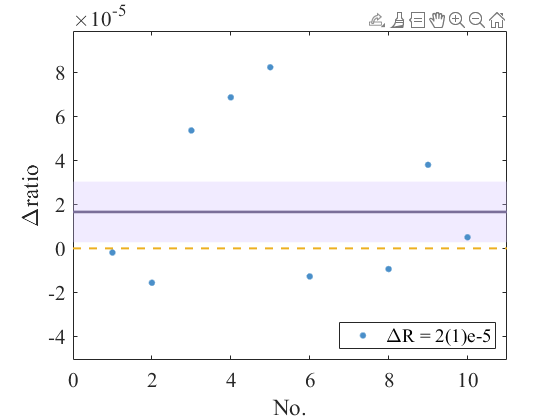


f1 = figure; hold on;

xmin = 0;
xman = diff_n+1;
ymin = min([-abs(drfm*0.2) min(diff_rf)*0.8 min(diff_rf)*1.2]);
ymax = max([abs(drfm*0.2) max(diff_rf)*0.8 max(diff_rf)*1.2]);

n1 = [1 2 3 4];
patch_list = [0 drfm-drfstd ; diff_n+1 drfm-drfstd ; diff_n+1 drfm+drfstd ; 0 drfm+drfstd];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l1 = plot([0 xman],[drfm drfm],Color=[0.48 0.43 0.60],LineWidth=2);

l2 = plot([1:diff_n],diff_rf,'.','MarkerSize',15);
%l2.MarkerEdgeColor = [0.04,0.59,0.83];
%l2.MarkerFaceColor = [0.29,0.91,0.91];
l2.Color = [0.29,0.56,0.79];

l3 = plot([0 xman],[0 0],'--','LineWidth',1.5,Color=[0.93 0.69 0.13]);

if diff_n < 6
    xticks([]);
end

xlim([xmin xman]);
ylim([ymin ymax]);

xlabel('No.');
%ylabel('\Deltafreq');
ylabel('\Deltaratio');
%legend('','',['\DeltaB = ',num2str(Bm,'%.2f'),'(',num2str(Bstd*1e2,'%.0f'),')'],'',...
%    'Location','southeast');
legend('','',['\DeltaR = ',num2str(drfm*1e5,'%.0f'),'(',num2str(drfstd*1e5,'%.0f'),')e-5'],'',...
    'Location','southeast');
grid off;
box on;

set(f1,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');

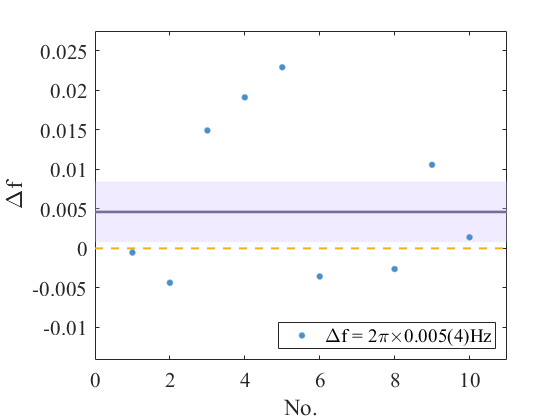


f2 = figure; hold on;

xmin = 0;
xman = diff_n+1;
ymin = min([-abs(dfm*0.2) min(df)*0.8 min(df)*1.2]);
ymax = max([abs(dfm*0.2) max(df)*0.8 max(df)*1.2]);

n1 = [1 2 3 4];
patch_list = [0 dfm-dfstd ; diff_n+1 dfm-dfstd ; diff_n+1 dfm+dfstd ; 0 dfm+dfstd];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l1 = plot([0 xman],[dfm dfm],Color=[0.48 0.43 0.60],LineWidth=2);

l2 = plot([1:diff_n],df,'.','MarkerSize',15);
%l2.MarkerEdgeColor = [0.04,0.59,0.83];
%l2.MarkerFaceColor = [0.29,0.91,0.91];
l2.Color = [0.29,0.56,0.79];

l3 = plot([0 xman],[0 0],'--','LineWidth',1.5,Color=[0.93 0.69 0.13]);

if diff_n < 6
    xticks([]);
end

xlim([xmin xman]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\Deltaf');
%ylabel('\Deltaratio');
legend('','',['\Deltaf = 2\pi\times',num2str(dfm,'%.3f'),'(',num2str(dfstd*1e3,'%.0f'),')Hz'],'',...
    'Location','southeast');
%legend('','',['\DeltaR = ',num2str(rm*1e5,'%.0f'),'(',num2str(rstd*1e5,'%.0f'),')e-5'],'',...
%    'Location','southeast');
grid off;
box on;

set(f2,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');

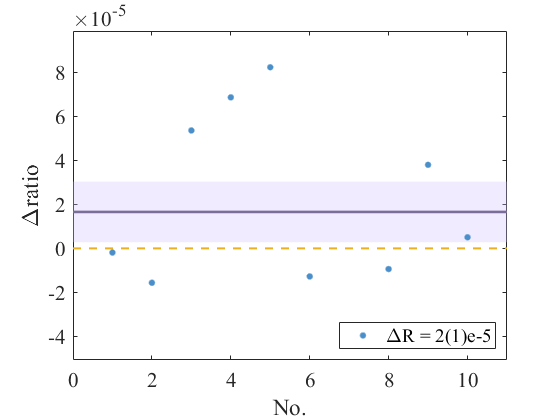


savefig(f1,[main_dir_0,'diffRf.fig']);
saveas(f1,[main_dir_0,'diffRf.png']);

savefig(f2,[main_dir_0,'diff_f.fig']);
saveas(f2,[main_dir_0,'diff_f.png']);


save([main_dir_0,'diffR.mat']);